% There are 116 masses in total.
clear all;
close all;
clc;

load INbreast_mass_contour.mat
total_mass_bbox = zeros(116, 4);
pointer = 1;
for j = 1:size(total_mass_contour, 1)
    current_mammography_mass_array = total_mass_contour{j, 1};
    num_of_mass_temp = length(current_mammography_mass_array);
    for i = 1:num_of_mass_temp
        data_temp = current_mammography_mass_array{i};
        total_mass_bbox(pointer, 1) = min(data_temp(:, 1));
        total_mass_bbox(pointer, 2) = max(data_temp(:, 1));
        total_mass_bbox(pointer, 3) = min(data_temp(:, 2));
        total_mass_bbox(pointer, 4) = max(data_temp(:, 2));
        pointer = pointer + 1;
        %     rectangle('Position', [x_min, y_min, x_max-x_min, y_max-y_min])
        %     plot([x_min, x_min], [y_min, y_max])
        %     plot([x_max, x_max], [y_min, y_max])
        %     plot([x_min, x_max], [y_min, y_min])
        %     plot([x_min, x_max], [y_max, y_max])
    end
end


clear all;
close all;
clc;

test = dicomread('51049107_8c105bb715bf1c3c_MG_L_CC_ANON.dcm')

test = 4084×3328 uint16 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

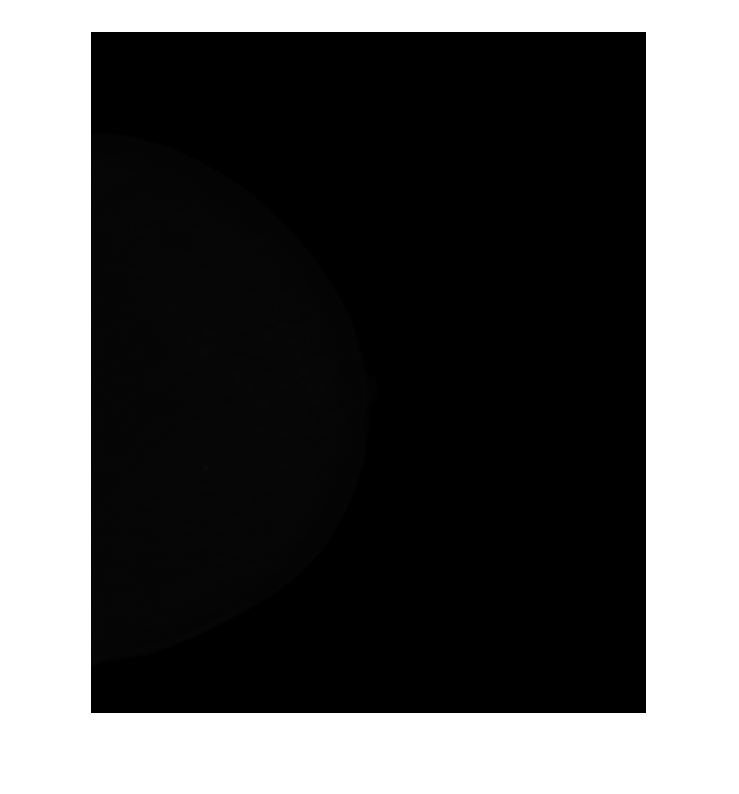

imshow(test)

clear all;
close all;
clc;

load INbreast_mass_bbox_statistic.mat;
load INbreast_mass_locations.mat;
load 20587928_objects.mat;

test = dicomread('53586960_809e3f43339f93c6_MG_L_ML_ANON.dcm');
imshow(test, [])

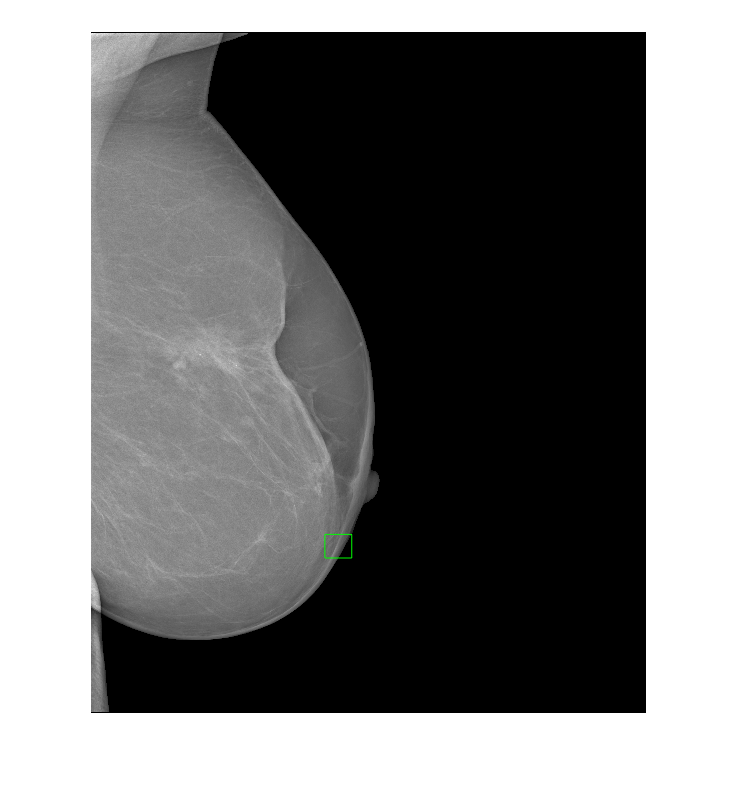

hold on;
location = total_mass_bbox(112, :);
rectangle('Position', [location(1), location(3), location(2) - location(1), location(4) - location(3)],'EdgeColor', 'g')

clear all;
close all;
clc;

load 53586960_objects.mat;
load INbreast_mass_locations.mat;

test = dicomread('53586960_809e3f43339f93c6_MG_L_ML_ANON.dcm');
imshow(test, [])

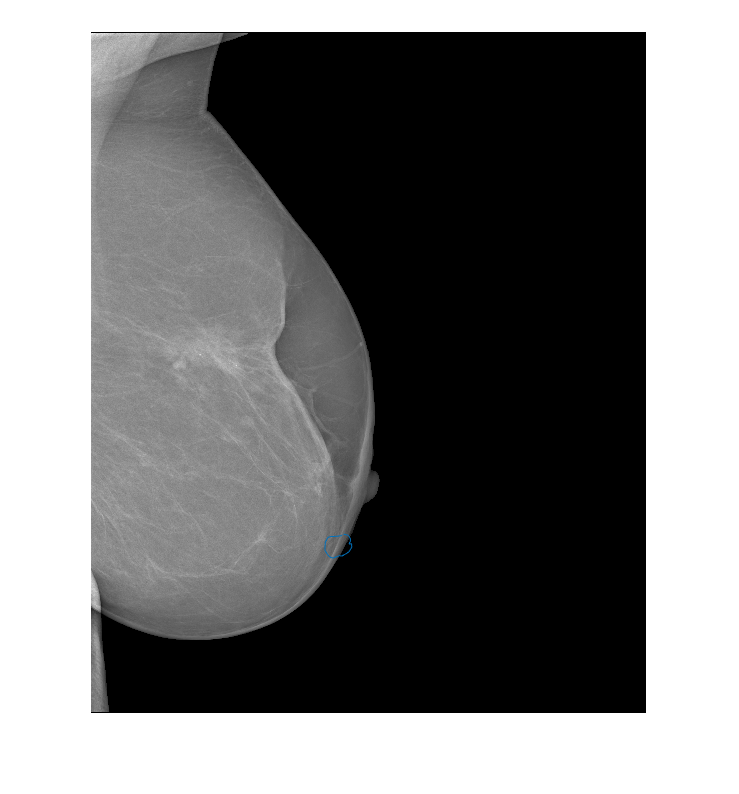

hold on;

plot(final_array_mass{328,1}{1}(:, 1), final_array_mass{328,1}{1}(:, 2))

clear all;
close all;
clc;

load INbreast_total_mass_bbox_statistic.mat;
load INbreast_mass_locations.mat;
load 53587014_objects.mat;

test = dicomread('53587014_809e3f43339f93c6_MG_L_CC_ANON.dcm');
imshow(test, [])

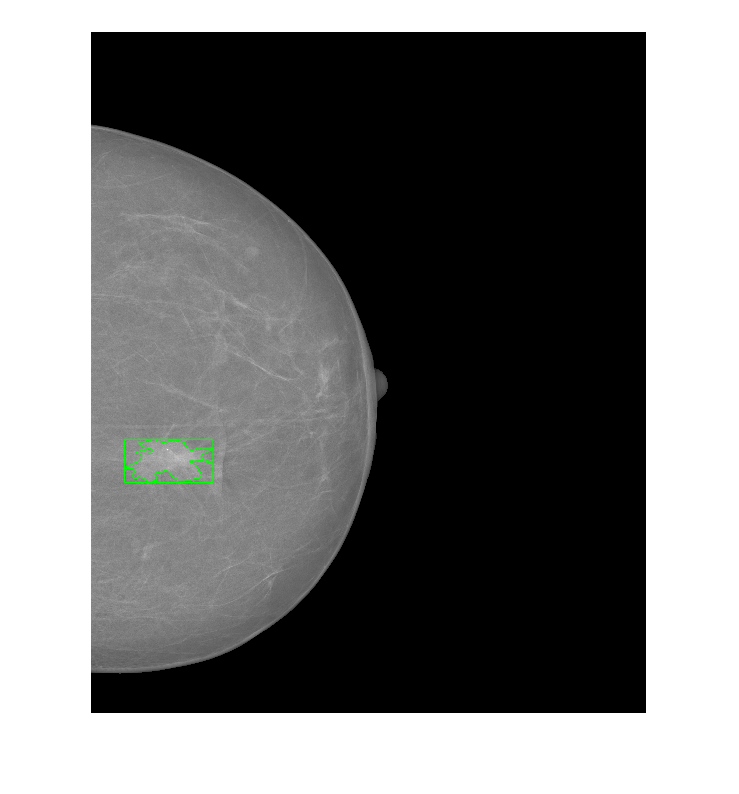

hold on;

location = total_mass_bbox(115, :);
% plot(masses{1}(:, 1), masses{1}(:, 2))
plot(final_array_mass{332, 1}{1}(:, 1), final_array_mass{332, 1}{1}(:, 2),'Color', 'g')
rectangle('Position', [location(1), location(3), location(2) - location(1), location(4) - location(3)],'EdgeColor', 'g')